# Create Tables and Assign Data to Them

Tables are suitable for column-oriented data such as tabular data from text files or spreadsheets. Tables store columns of data in variables. The variables in a table can have different data types, though all of the variables must have the same number of rows. However, table variables are not restricted to storing only column vectors. For example, a table variable can contain a matrix with multiple columns as long as it has the same number of rows as the other table variables.

In MATLAB®, you can create tables and assign data to them in several ways.

- Create a table from input arrays by using the `table` function.

- Add variables to an existing table by using dot notation.

- Assign variables to an empty table.

- Preallocate a table and fill in its data later.

- Convert variables to tables by using the `array2table`, `cell2table`, or `struct2table` functions.

- Read a table from file by using the `readtable` function.

- Import a table using the **Import Tool**.

The way you choose depends on the nature of your data and how you plan to use tables in your code.

## Create Tables from Input Arrays

You can create a table from arrays by using the `table` function. For example, create a small table with data for five patients.

First, create six column-oriented arrays of data. These arrays have five rows because there are five patients. (Most of these arrays are 5-by-1 column vectors, while `BloodPressure` is a 5-by-2 matrix.)

LastName = ["Sanchez";"Johnson";"Zhang";"Diaz";"Brown"];
Age = [38;43;38;40;49];
Smoker = [true;false;true;false;true];
Height = [71;69;64;67;64];
Weight = [176;163;131;133;119];
BloodPressure = [124 93; 109 77; 125 83; 117 75; 122 80];

Now create a table, `patients`, as a container for the data. In this call to the `table` function, the input arguments use the workspace variable names for the names of the variables in `patients`.

patients = table(LastName,Age,Smoker,Height,Weight,BloodPressure)

The table is a 5-by-6 table because it has six variables. As the `BloodPressure` variable shows, a table variable itself can have multiple columns. This example shows why tables have rows and variables, not rows and columns.

## Add Variable to Table Using Dot Notation

Once you have created a table, you can add a new variable at any time by using *dot notation*. Dot notation refers to table variables by name, `T.varname`, where `T` is the table and `varname` is the variable name. This notation is similar to the notation you use to access and assign data to the fields of a structure.

For example, add a `BMI` variable to `patients`. Calculate body mass index, or BMI, using the values in `patients.Weight` and `patients.Height`. Assign the BMI values to a new table variable.

patients.BMI = (patients.Weight*0.453592)./(patients.Height*0.0254).^2

## Assign Variables to Empty Table

Another way to create a table is to start with an empty table and assign variables to it. For example, re-create the table of patient data, but this time assign variables using dot notation.

First, create an empty table, `patients2`, by calling `table` without arguments.

patients2 = table

Next, create a copy of the patient data by assigning variables. Table variable names do not have to match array names, as shown by the `Name` and `BP` table variables.

patients2.Name = LastName;
patients2.Age = Age;
patients2.Smoker = Smoker;
patients2.Height = Height;
patients2.Weight = Weight;
patients2.BP = BloodPressure

## Preallocate Table and Fill Rows

Sometimes you know the sizes and data types of the data that you want to store in a table, but you plan to assign the data later. Perhaps you plan to add only a few rows at a time. In that case, *preallocating* space in the table and then assigning values to empty rows can be more efficient.

For example, to preallocate space for a table to contain time and temperature readings at different stations, use the `table` function. Instead of supplying input arrays, specify the sizes and data types of the table variables. To give them names, specify the `'VariableNames'` argument. Preallocation fills table variables with default values that are appropriate for their data types.

sz = [4 3];
varTypes = ["double","datetime","string"];
varNames = ["Temperature","Time","Station"];
temps = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames)

One way to assign or add a row to a table is to assign a cell array to a row. If the cell array is a row vector and its elements match the data types of their respective variables, then the assignment converts the cell array to a table row. However, you can assign only one row at a time using cell arrays. Assign values to the first two rows.

temps(1,:) = {75,datetime('now'),"S1"};
temps(2,:) = {68,datetime('now')+1,"S2"}

As an alternative, you can assign rows from a smaller table into a larger table. With this method, you can assign one or more rows at a time.

temps(3:4,:) = table([63;72],[datetime('now')+2;datetime('now')+3],["S3";"S4"])

You can use either syntax to increase the size of a table by assigning rows beyond the end of the table. If necessary, missing rows are filled in with default values.

temps(6,:) = {62,datetime('now')+6,"S6"}

## Convert Variables to Tables

You can convert variables that have other data types to tables. Cell arrays and structures are other types of containers that can store arrays that have different data types. So you can convert cell arrays and structures to tables. You can also convert an array to a table where the table variables contain columns of values from the array. To convert these kinds of variables, use the `array2table`, `cell2table`, or `struct2table` functions.

For example, convert an array to a table by using `array2table`. Arrays do not have column names, so the table has default variable names.

A = randi(3,3)
a2t = array2table(A)

You can provide your own table variable names by using the `"VariableNames"` name-value argument.

a2t = array2table(A,"VariableNames",["First","Second","Third"])

## Read Table from File

It is common to have a large quantity of tabular data in a file such as a CSV (comma-separated value) file or an Excel® spreadsheet. To read such data into a table, use the `readtable` function.

For example, the CSV file `outages.csv` is a sample file that is distributed with MATLAB. The file contains data for a set of electrical power outages. The first line of `outages.csv` has column names. The rest of the file has comma-separated data values for each outage. The first few lines are shown here.

To read `outages.csv` and store the data in a table, you can use `readtable`. It reads numeric values, dates and times, and strings into table variables that have appropriate data types. Here, `Loss` and `Customers` are numeric arrays. The `OutageTime` and `RestorationTime` variables are `datetime` arrays because `readtable` recognizes the date and time formats of the text in those columns of the input file. To read the rest of the text data into string arrays, specify the `"TextType"` name-value argument.

outages = readtable("outages.csv","TextType","string")

## Import Table Using Import Tool

Finally, you can interactively preview and import data from spreadsheets or delimited text files by using the **Import Tool**. There are two ways to open the **Import Tool**.

- MATLAB Toolstrip: On the **Home** tab, in the **Variable** section, click **Import Data**.

- MATLAB command prompt: Enter `uiimport(``filename``)`, where `filename` is the name of a text or spreadsheet file.

For example, open the `outages.csv` sample file by using `uiimport` and `which` to get the path to the file.

`uiimport(which("outages.csv"))`

The **Import Tool** shows you a preview of the six columns from `outages.csv`. To import the data as a table, follow these steps.

- In the **Imported Data** section, select **Table** as the output type.

- Click **Import Selection** (near the upper-right corner). The new table, named `outages`, appears in your workspace.

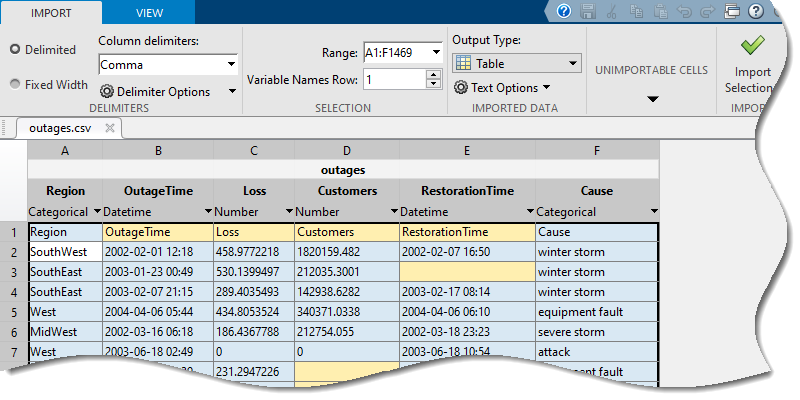

*Copyright 2012-2021 The MathWorks, Inc.*